# 3.2 向量

## 1.向量的创建方法

- 向量可以被看做一维数组

- 矩阵为二维数组

- 多维数组也能在matlab定义,后续自己学

**方法1:直接输入法**

        向量元素需要用中括号“［］”括起来，元素之间用空格、逗号、分号或按回车键分隔，就可以创建对应的向量。

        若元素之间用 **空格、逗号** 分隔，则创建的是 **行向量** ；若用 **分号、回车键** 分隔，则创建的是 **列向量** 。

a = [1 3 5]

a =      1     3     5


a = [1 , 3 , 5]

a =      1     3     5


b = [1 ; 2 ; 3]

b =      1
     2
     3


b = [1
    2
    3]

b =      1
     2
     3


**方法2:冒号法**

语法: **A:step:B**  (无需使用方括号 , A 和 B 都包含在其中)

a = 1 : 2 : 7   % 单增

a =      1     3     5     7


a = 10:-1:3     % 单减

a =     10     9     8     7     6     5     4     3


a = 1:2:8       % 不会小于A,超过Ba = 1:2:8       % 不会小于A,超过B

a =      1     3     5     7


a_NULL = 5:2:1       % 接上句,否则就为NULL , 步长为0也是NULL


a_NULL =

  空的 1×0 double 行向量



a_null = []              % 空向量,与上面的空向量相同


a_null =

     []



**方法3: 使用MATLAB函数创建**

① linspace : 创建等差数列(行向量)

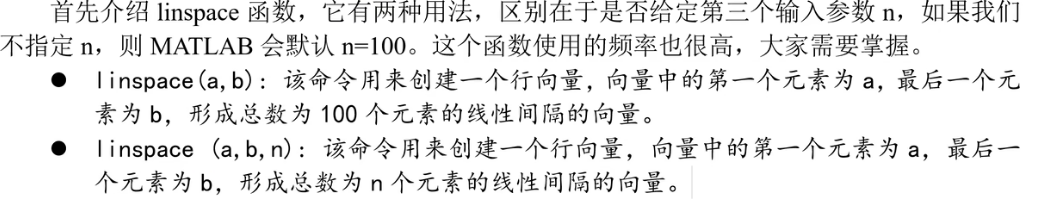

a_3_1 = linspace(100,1)       % 默认创建100个等差数据

a_3_1 =    100    99    98    97    96    95    94    93    92    91    90    89    88    87    86    85    84    83    82    81    80    79    78    77    76    75    74    73    72    71    70    69    68    67    66    65    64    63    62    61    60    59    58    57    56    55    54    53    52    51


a_3_2 = linspace(1 , 2 , 5) % 创建总共5个数据

a_3_2 =                          1                      1.25                       1.5                      1.75                         2


- 总结:和"冒号法"的区别:

- linspace不需要指定步长,并且最后一个元素一定是b,但是冒号不一定最后一个为b

②logspace

logspace(1,3,3) % 10^A 到 10^B , n 为数组总数

ans =           10         100        1000


logspace(1,3)   % 默认为50项

ans =                         10          10.9854114198756          12.0679264063933          13.2571136559011          14.5634847750124          15.9985871960606          17.5751062485479          19.3069772888325          21.2095088792019          23.2995181051537          25.5954792269954          28.1176869797423          30.8884359647748          33.9322177189533          37.2759372031494          40.9491506238043          44.9843266896944          49.4171336132383          54.2867543932386          59.6362331659464          65.5128556859551          71.9685673001152           79.060432109077          86.8511373751353          95.4095476349994          104.811313415469          115.139539932645           126.48552168553          138.949549437314          152.641796717523          167.683293681101          184.206996932672          202.358964772516           222.29964825262          244.205309454865          268.269579527973          294.705170255181          323.745754281764      

## 2. 向量元素的引用

### 2-1 向量包含的元素个数计算

- length函数 / numel函数

a = 1:2:9;
length(a)

ans = 5

numel(a)

ans = 5

### 2-2 向量的引用

- MATLAB的索引从1开始!

#### 2-2-1 单个元素引用

arr(n) -> an元素

a(1)

ans = 1

% a(6)

#### 2-2-2 多个元素引用

arr([数组])

a([1 2 2 2 4])  % arr( [数组值] )

ans =      1     3     3     3     7


#### 2-2-3 技巧 : 使用end索引

- 即使用end代表最后一个元素

a(1:2:end)    % 想要 1 , 3 , 5位置的元素(end代表最后一个元素)

ans =      1     5     9


- 还可以进行end - k

a(1:2:end-1)

ans =      1     5


## 3. 向量元素的修改和删除

a = 2:2:10

a =      2     4     6     8    10


### 3-1 向量元素的修改

① 单个修改

a(1) = 4

a =      4     4     6     8    10


② 多个修改

a([1,3]) = [5 9]

a =      5     4     9     8    10


③ 冒号修改 + 修改为同一个数据

a(1:1:3) = 100

a =    100   100   100     8    10


### 3-2 向量元素的删除

①单个删除

a(1) = []

a =    100   100     8    10


②多个删除

a(end:-1:end-1) = []

a =    100   100


## 4. 总结

- 关于括号:

- [ ] 为数组

- ( )为向量 , 对向量执行操作放入的是数组 如 a( [2 , 3] ) = 100